# Lab 1

## A little statistics

### Section 1: Finding the probabilities and sigmas of normal distributions.

clc; clear; close all;

% Integrating the normal distribution to find probability.
a1 = normcdf(1); % z-table lookup is 0.84134
disp(a1);

    0.8413



a2 = normcdf(2); % z-table is 0.97725
disp(a2);

    0.9772



a3 = normcdf(-1); % calculated 0.1587 from z-table values
disp(a3);

    0.1587




% Finding sigma from probability.
b1 = norminv(0.84134); % expecting 1 sigma
disp(b1);

    1.0000



b2 = norminv(0.97725); % expecting 2 sigma
disp(b2);

    2.0000



b3 = norminv(2.86652E-7); % expecting 5 sigma
disp(b3);

   -5.0000



The sign on the norminv() output tells us the direction, left or right from the mean, in which the sigma lies. A negative sigma will be to the left, positive to the right. Observing the sign helps us determine which side of the distribution we are on. In the case where we use norminv() directly on a small probability for a correspondingly high positive sigma, then we shouldn't be surprised by the appearance of a negative sign and we may safely discard it if speaking in terms of magnitude.

### Section 2: Exploring the lognormal distribution.

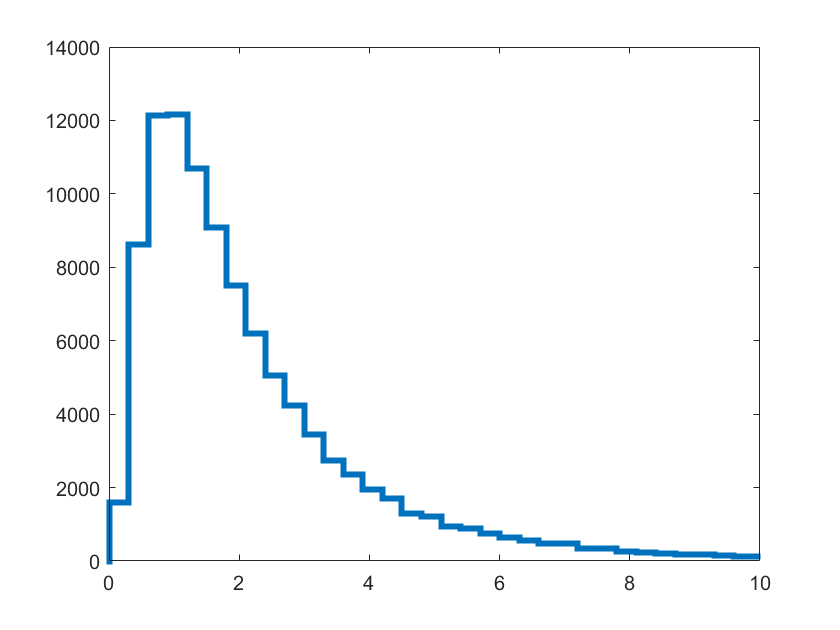

clc; clear; close all;

% analytic pdf() versus samples w/ built-in distribution
mu = 0.5;
sigma = 0.8;

logNorm = random('Lognormal',mu,sigma,[1,100000]);
histogram(logNorm,200,'DisplayStyle',"stairs",'LineWidth',3);
xlim([0,10]);

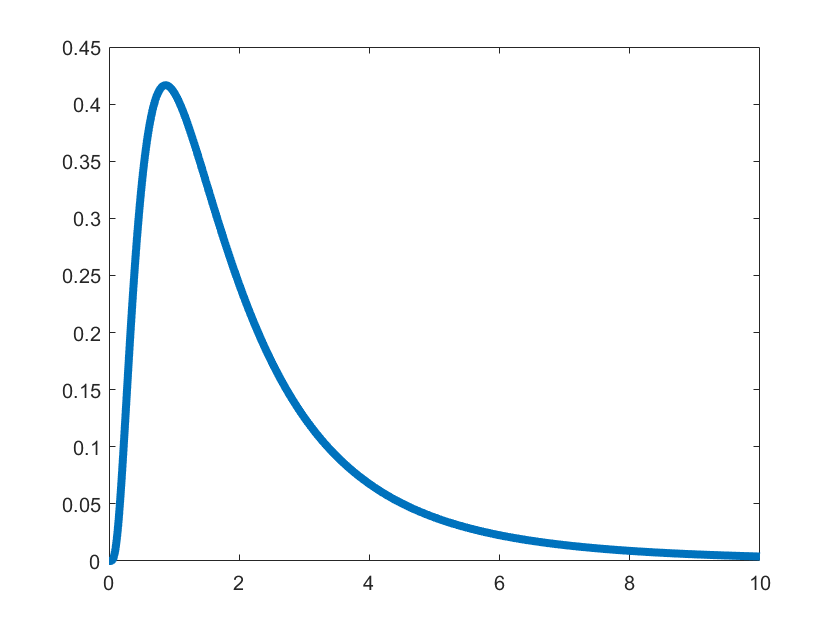


x = linspace(0,10,1000);
logN = makedist("Lognormal",'mu',mu,'sigma',sigma);
plot(x,pdf(logN,x),"LineWidth",4);

### Section 3: Determining measurement sigma with the signal-free data (lognormal).

For an imagined signal-free data following the lognormal distribution, consider a hypothetical measurement of 9. What then is the likelihood that the random signal-free data will produce a value equal to or greater than 9?

Written in integral form:$\int_9^{\infty } \mathrm{pdf}\left(x\right)\mathrm{dx}$

Probability calculation:

z = cdf(logN,9,'upper');
disp(z);

    0.0169



Converting probability to an equivalent 'sigma':

c1 = abs(norminv(z));
disp(c1);

    2.1215



Equivalent is then just over two sigma.

### Section 4: Exploration and Patterns.

Adjusting the hypothetical measurement value to be farther away from the mean causes the probability to decrease and the 'sigmas' to increase. Probability changes more rapidly closer to the mean (more area per step under the curve). At higher than a couple of 'sigmas' the probability becomes incredibly low.

## Non-continuous distributions.

The Poisson distribution is the limiting case of the Binomial distribution where the number of trials goes to infinity. It gives the probability that a certain number of events within a fixed interval may occur.

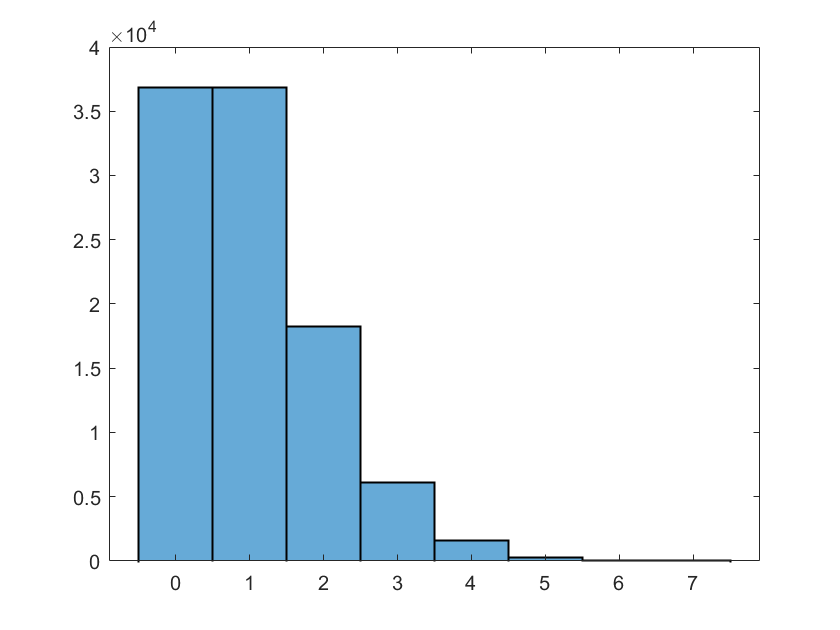

clc; close all; clear;
expected1 = 1;
expected2 = 4;
expected3 = 8;
hpoisson1 = random('Poisson',expected1,[1,100000]);
hpoisson2 = random('Poisson',expected2,[1,100000]);
hpoisson3 = random('Poisson',expected3,[1,100000]);
histogram(hpoisson1,'DisplayStyle',"bar",'LineWidth',1);

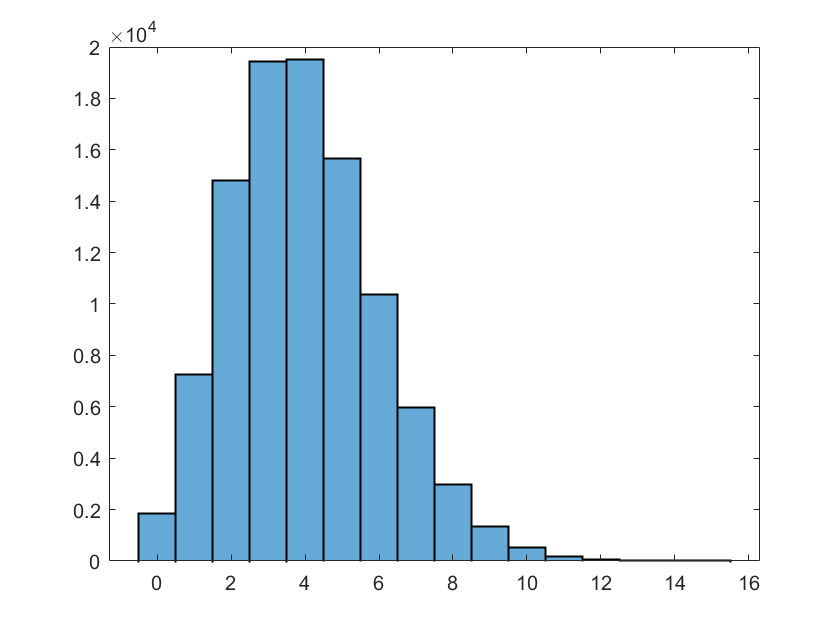

histogram(hpoisson2,'DisplayStyle',"bar",'LineWidth',1);

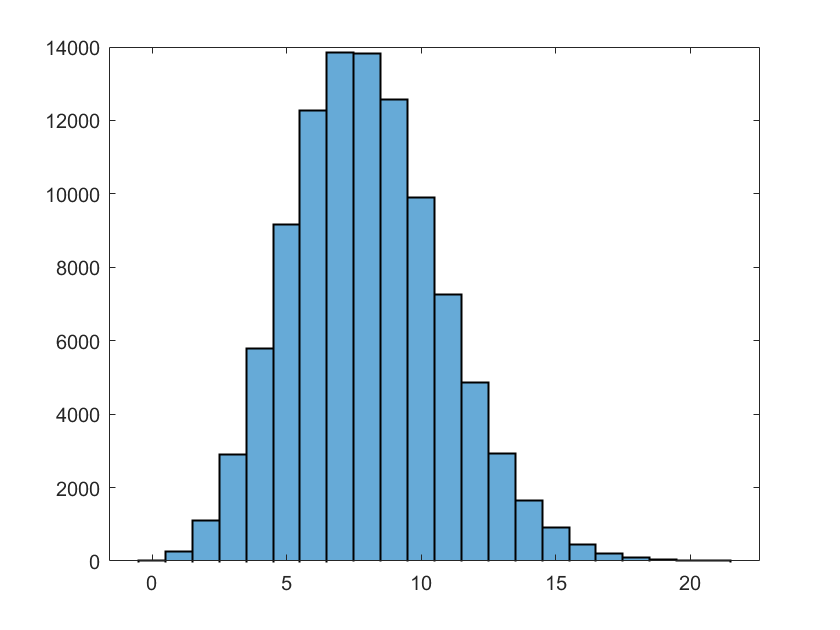

histogram(hpoisson3,'DisplayStyle',"bar",'LineWidth',1);

In these plots, the counted events cluster around the expected value and fall off the farther away from it you get. When the expected value is low (close to zero) a greater number of events fall within the lowest bin because events cannot occur fewer than zero times, giving the graph an asymmetric shape. Higher expected values result in more symmetrical distributions.

Hypothetical question: What is the probability that the random signal-free data (which follows the poisson distribution) will be greater than or equal to the number of events I measure in the same fixed interval?

If I measure 20, and the expected number of occurances for the signal-free data is 8, then:

lambda = 8;
dpoisson = makedist('Poisson',lambda);
dprob = cdf(dpoisson,20,'upper');
disp(dprob);

   9.3968e-05



dsigma = abs(norminv(dprob));
disp(dsigma);

    3.7347



The probability of randomly getting 20 or more events is very low, resulting in a correspondingly large sigma value.

The probabilities and 'sigmas' are discrete in the sense that each whole number bin has a defined probability associated with it (there exists no probability of a measurement between bins) and any interval will be the sum of the probabilities for each bin. As a consequence, the 'sigmas' we calculate from these probabilities will also be, arguably, discrete in nature. An implication of this is that in our experiments we are bound to these values; we cannot impose probabilities or 'sigmas' without carefully considering the discrete nature of events. From an initial arbitrary choice we may consider nearby discrete values and what it means for the experiment to move between them, but there may be a significant jump in probability between the different outcomes.

The mean (the expected value) of the Poisson distribution can be a positive non-integer as a mathematical consequence of averaging the data we collect. This makes sense because while the mean takes on a continuous range of values, the outcomes themselves around that mean are still discrete. We can assemble the necessary distribution of discrete events to produce any desired mean (provided it is a real number) by expressing the mean as the fraction of two whole numbers: the numerator is the total events and the denominator is the number of samples. Probability weights may then be considered to 'shape' the distribution as needed.